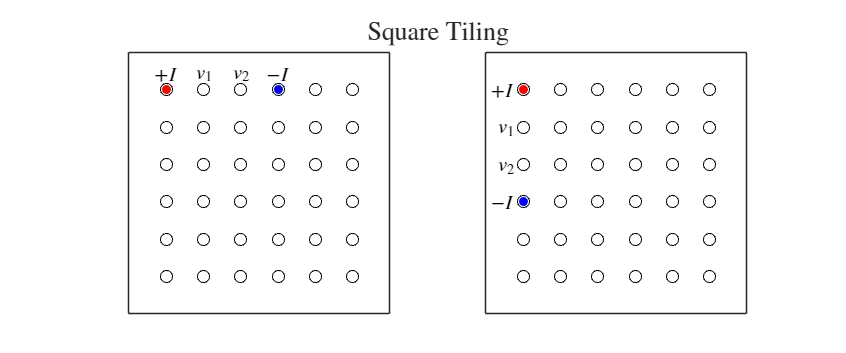

clear
clc
sz = 36;

N = 6;
M = 6;
squareGrid.x = 1:N;
squareGrid.y = 1:M;
fig = figure("Position",[0,0,1200,500]);
t = tiledlayout(1,2,"TileSpacing","compact");
title(t,"Square Tiling","Interpreter","Latex");
nexttile;
for j = 1:M
    scatter(squareGrid.x,squareGrid.y(j),sz,'k')
    hold on
end
scatter(squareGrid.x(1),squareGrid.y(end),5*sz,'r.')
scatter(squareGrid.x(4),squareGrid.y(end),5*sz,'b.')
text(squareGrid.x(1),squareGrid.y(end) + 0.1,"$+I$", ...
    'Interpreter','latex', ...
    "HorizontalAlignment","center", ...
    "VerticalAlignment","bottom")
text(squareGrid.x(2),squareGrid.y(end) + 0.1,"$v_1$", ...
    'Interpreter','latex', ...
    "HorizontalAlignment","center", ...
    "VerticalAlignment","bottom")
text(squareGrid.x(3),squareGrid.y(end) + 0.1,"$v_2$", ...
    'Interpreter','latex', ...
    "HorizontalAlignment","center", ...
    "VerticalAlignment","bottom")
text(squareGrid.x(4),squareGrid.y(end) + 0.1,"$-I$", ...
    'Interpreter','latex', ...
    "HorizontalAlignment","center", ...
    "VerticalAlignment","bottom")
hold off
box on
axis equal
xticks(-1);
yticks(-1);
xlim([0,N+1])
ylim([0,M+1])

nexttile;
for j = 1:M
    scatter(squareGrid.x,squareGrid.y(j),sz,'k')
    hold on
end
scatter(squareGrid.x(1),squareGrid.y(end),5*sz,'r.')
scatter(squareGrid.x(1),squareGrid.y(end-3),5*sz,'b.')
text(squareGrid.x(1) - 0.2,squareGrid.y(end),"$+I$", ...
    'Interpreter','latex', ...
    "HorizontalAlignment","right", ...
    "VerticalAlignment","middle")
text(squareGrid.x(1) - 0.2,squareGrid.y(end-1),"$v_1$", ...
    'Interpreter','latex', ...
    "HorizontalAlignment","right", ...
    "VerticalAlignment","middle")
text(squareGrid.x(1) - 0.2,squareGrid.y(end-2),"$v_2$", ...
    'Interpreter','latex', ...
    "HorizontalAlignment","right", ...
    "VerticalAlignment","middle")
text(squareGrid.x(1) - 0.2,squareGrid.y(end-3),"$-I$", ...
    'Interpreter','latex', ...
    "HorizontalAlignment","right", ...
    "VerticalAlignment","middle")
hold off
box on
axis equal
xticks(-1);
yticks(-1);
xlim([0,N+1])
ylim([0,M+1])
saveas(fig,"sqTile.svg","svg")

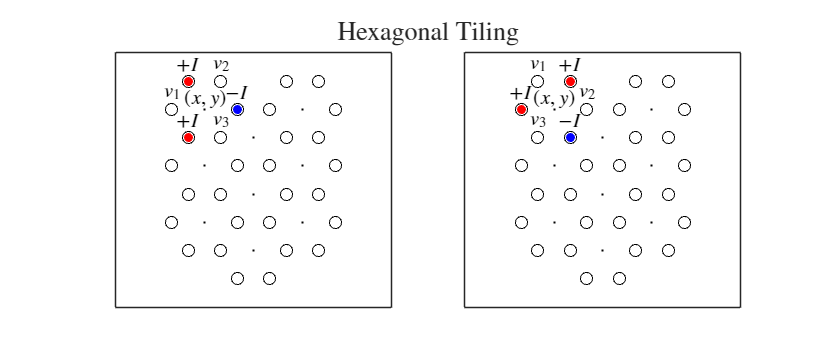

clear
clc
sz = 36;

N = 3;
M = 3;
r = 1/2;
R = sqrt(3) * r;
hexGrid.x = 1:R:N;
hexGrid.y = 1:2*r:M;
fig = figure("Position",[0,0,1200,500]);
t = tiledlayout(1,2,"TileSpacing","compact");
title(t,"Hexagonal Tiling","Interpreter","Latex");
nexttile;
for j = 1:length(hexGrid.y)
    for i = 1:length(hexGrid.x)
        if (mod(i,2) == 0)
            hexGrid.y(j) = hexGrid.y(j) - r;
        end
        scatter(hexGrid.x(i),hexGrid.y(j),sz/10,'.k')
        hold on
        scatter(hexGrid.x(i) + sqrt(3)*r/3,hexGrid.y(j) + r,sz,'k')
        scatter(hexGrid.x(i) + sqrt(3)*r/3,hexGrid.y(j) - r,sz,'k')
        scatter(hexGrid.x(i) - sqrt(3)*r/3,hexGrid.y(j) + r,sz,'k')
        scatter(hexGrid.x(i) - sqrt(3)*r/3,hexGrid.y(j) - r,sz,'k')
        scatter(hexGrid.x(i) + 2*R/3,hexGrid.y(j),sz,'k')
        scatter(hexGrid.x(i) - 2*R/3,hexGrid.y(j),sz,'k')
        if (mod(i,2) == 0)
            hexGrid.y(j) = hexGrid.y(j) + r;
        end
    end
end
scatter(hexGrid.x(1) - sqrt(3)*r/3,hexGrid.y(end) + r,5*sz,'r.')
scatter(hexGrid.x(1) - sqrt(3)*r/3,hexGrid.y(end) - r,5*sz,'r.')
scatter(hexGrid.x(1) + 2*R/3,hexGrid.y(end),5*sz,'b.')
text(hexGrid.x(1) - sqrt(3)*r/3,hexGrid.y(end) + r + 0.1,"$+I$", ...
    'Interpreter','latex', ...
    "HorizontalAlignment","center", ...
    "VerticalAlignment","bottom")
text(hexGrid.x(1) - sqrt(3)*r/3,hexGrid.y(end) - r + 0.1,"$+I$", ...
    'Interpreter','latex', ...
    "HorizontalAlignment","center", ...
    "VerticalAlignment","bottom")
text(hexGrid.x(1) + 2*R/3,hexGrid.y(end) + 0.1,"$-I$", ...
    'Interpreter','latex', ...
    "HorizontalAlignment","center", ...
    "VerticalAlignment","bottom")
text(hexGrid.x(1) - 2*R/3,hexGrid.y(end) + 0.1,"$v_1$", ...
    'Interpreter','latex', ...
    "HorizontalAlignment","center", ...
    "VerticalAlignment","bottom")
text(hexGrid.x(1) + sqrt(3)*r/3,hexGrid.y(end) + r + 0.1,"$v_2$", ...
    'Interpreter','latex', ...
    "HorizontalAlignment","center", ...
    "VerticalAlignment","bottom")
text(hexGrid.x(1) + sqrt(3)*r/3,hexGrid.y(end) - r + 0.1,"$v_3$", ...
    'Interpreter','latex', ...
    "HorizontalAlignment","center", ...
    "VerticalAlignment","bottom")
text(hexGrid.x(1),hexGrid.y(end),"$(x,y)$", ...
    'Interpreter','latex', ...
    "HorizontalAlignment","center", ...
    "VerticalAlignment","bottom")
hold off
box on
axis equal
xticks(-2);
yticks(-2);
ylim([hexGrid.y(1)-3*r,hexGrid.y(end)+2*r])

nexttile;
for j = 1:length(hexGrid.y)
    for i = 1:length(hexGrid.x)
        if (mod(i,2) == 0)
            hexGrid.y(j) = hexGrid.y(j) - r;
        end
        scatter(hexGrid.x(i),hexGrid.y(j),sz/10,'.k')
        hold on
        scatter(hexGrid.x(i) + sqrt(3)*r/3,hexGrid.y(j) + r,sz,'k')
        scatter(hexGrid.x(i) + sqrt(3)*r/3,hexGrid.y(j) - r,sz,'k')
        scatter(hexGrid.x(i) - sqrt(3)*r/3,hexGrid.y(j) + r,sz,'k')
        scatter(hexGrid.x(i) - sqrt(3)*r/3,hexGrid.y(j) - r,sz,'k')
        scatter(hexGrid.x(i) + 2*R/3,hexGrid.y(j),sz,'k')
        scatter(hexGrid.x(i) - 2*R/3,hexGrid.y(j),sz,'k')
        if (mod(i,2) == 0)
            hexGrid.y(j) = hexGrid.y(j) + r;
        end
    end
end
scatter(hexGrid.x(1) + sqrt(3)*r/3,hexGrid.y(end) + r,5*sz,'r.')
scatter(hexGrid.x(1) + sqrt(3)*r/3,hexGrid.y(end) - r,5*sz,'b.')
scatter(hexGrid.x(1) - 2*R/3,hexGrid.y(end),5*sz,'r.')
text(hexGrid.x(1) - sqrt(3)*r/3,hexGrid.y(end) + r + 0.1,"$v_1$", ...
    'Interpreter','latex', ...
    "HorizontalAlignment","center", ...
    "VerticalAlignment","bottom")
text(hexGrid.x(1) - sqrt(3)*r/3,hexGrid.y(end) - r + 0.1,"$v_3$", ...
    'Interpreter','latex', ...
    "HorizontalAlignment","center", ...
    "VerticalAlignment","bottom")
text(hexGrid.x(1) + 2*R/3,hexGrid.y(end) + 0.1,"$v_2$", ...
    'Interpreter','latex', ...
    "HorizontalAlignment","center", ...
    "VerticalAlignment","bottom")
text(hexGrid.x(1) - 2*R/3,hexGrid.y(end) + 0.1,"$+I$", ...
    'Interpreter','latex', ...
    "HorizontalAlignment","center", ...
    "VerticalAlignment","bottom")
text(hexGrid.x(1) + sqrt(3)*r/3,hexGrid.y(end) + r + 0.1,"$+I$", ...
    'Interpreter','latex', ...
    "HorizontalAlignment","center", ...
    "VerticalAlignment","bottom")
text(hexGrid.x(1) + sqrt(3)*r/3,hexGrid.y(end) - r + 0.1,"$-I$", ...
    'Interpreter','latex', ...
    "HorizontalAlignment","center", ...
    "VerticalAlignment","bottom")
text(hexGrid.x(1),hexGrid.y(end),"$(x,y)$", ...
    'Interpreter','latex', ...
    "HorizontalAlignment","center", ...
    "VerticalAlignment","bottom")
hold off
box on
axis equal
xticks(-2);
yticks(-2);
ylim([hexGrid.y(1)-3*r,hexGrid.y(end)+2*r])
saveas(fig,"hexTile.svg","svg")